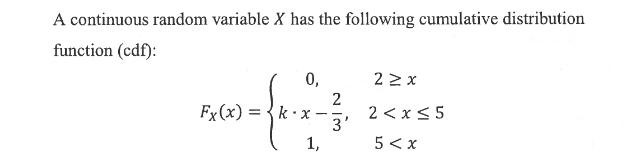

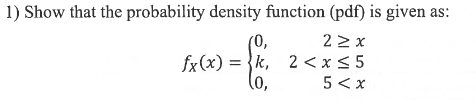


$$\begin{array}{l}
\mathrm{Tæthedsfunktionen}\;\mathrm{er}\;\mathrm{givet}\;\mathrm{ved}\;\left(\mathrm{cdf}\;\mathrm{differentieret}\;\mathrm{giver}\;\mathrm{pdf}\right)\\
f_x \left(x\right)=\frac{{\mathrm{dF}}_x \left(x\right)}{\mathrm{dx}}\\
-\\
2\;\ge \;x:\frac{{\mathrm{dF}}_x \left(x\right)}{\mathrm{dx}}=\frac{\mathrm{d0}}{\;\mathrm{dx}}=0\\
-\\
2<x\le 5:\frac{{\mathrm{dF}}_x \left(x\right)}{\mathrm{dx}}=\frac{d\left(k\cdot x-\frac{2}{3}\right)}{\mathrm{dx}}=k\\
\mathrm{for}\;\mathrm{at}\;\mathrm{være}\;\mathrm{sikre}\;\mathrm{kan}\;\mathrm{vi}\;\mathrm{differentiere}\;\mathrm{denne}\;\mathrm{funktion}\;i\;\mathrm{mathcad}
\end{array}$$



$$\begin{array}{l}
-\\
5<x:\frac{{\mathrm{dF}}_x \left(x\right)}{\mathrm{dx}}=\frac{\mathrm{d0}}{\;\mathrm{dx}}=0\;\\
\mathrm{Ligesom}\;\mathrm{for}\;2\ge x\;\mathrm{kan}\;\mathrm{vi}\;\mathrm{udføre}\;\mathrm{samme}\;\mathrm{udregning}\;\mathrm{og}\;\mathrm{få}\;\mathrm{samme}\;\mathrm{resultat}\ldotp 
\end{array}$$


Vi ved at for alle mulige værdier ved vi at resultatet skal give 1. I dette eksperiment er vores samplespace et interval fra 2-5, derfor kan vi opskrive nedenstående funktion.


$$\int_{-\infty \;}^{\infty } f_x \left(x\right)\;\mathrm{dx}=1\Rightarrow \int_{2\;}^5 k\;\mathrm{dx}=1\Rightarrow k=\frac{1}{3}$$


Ved brug af mathcad kan vi sikre os svaret 

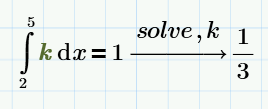

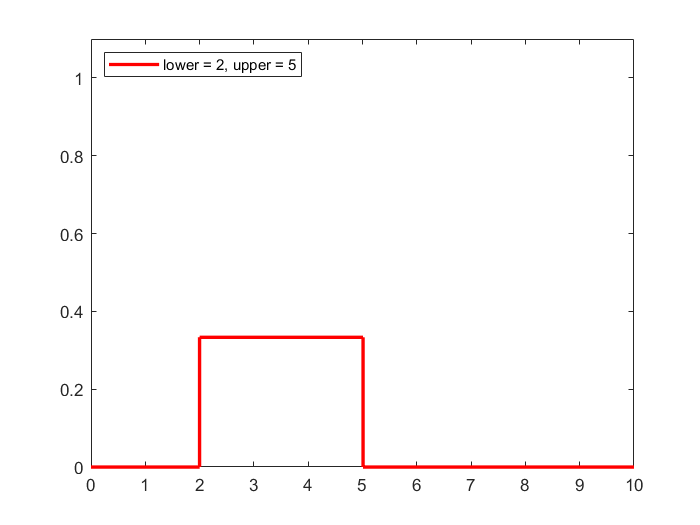

% Create three distribution objects with different parameters
pd1 = makedist('Uniform','lower',2,'upper',5);

% Compute the pdfs
x = 0:.01:10;
pdf1 = pdf(pd1,x);

% Plot the pdfs
figure;
stairs(x,pdf1,'r','LineWidth',2);
hold on;
ylim([0 1.1]);
legend({'lower = 2, upper = 5'},'Location','NW');
hold off;

En skitse af tæthedsfunktionen kan ses på grafen. Navnet på fordelingfunktionen er en uniformfordeling $U\left(2,5\right)$

For at beregne $\mathrm{Pr}\left(x\ge 3\right)$ skal vi udregne sandsynligheden for at $\mathrm{Pr}\left(x<3\right)$. Det udregner vi ved at indsætte 3 i vores CDF hvilket betyder at vi skal udregne $F_x \left(x=3\right)$ (det er det samme som $F_x \left(3\right)$). Når dette er udregnet trækker vi resultatet fra 1. så vi ender med $1-F_x \left(x=3\right)=1-\mathrm{Pr}\left(x<3\right)=\mathrm{Pr}\left(x\ge 3\right)$

1-((1/3)*3-(2/3))

ans = 0.6667

0.6667 svarer til $\frac{2}{3}$, hvilket betyder at $\mathrm{Pr}\left(x\ge 3\right)=\frac{2}{3}$

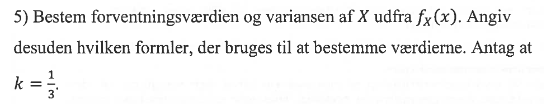

**NOTE:Forventningsværdi=Expected value**

**NOTE:Varians = Variance**

***EXPECTED VALUE:***

Ved antagelsen at $k=\frac{1}{3}$ kan vi skrive $f_x \left(x\right)$ således:


$$f_x \left(x\right)=\frac{1}{3}$$


For udregning af forventningsværdi bruger vi denne formel:


$$E\left\lbrack X\right\rbrack =\int_{-\infty \;}^{\infty } {x\cdot f}_x \left(x\right)\textrm{dx}$$


hvilket giver os: 


$$E\left\lbrack X\right\rbrack =\int_{-\infty \;}^{\infty } {x\cdot f}_x \left(x\right)\mathrm{dx}=\int_2^5 x\cdot \frac{1}{3}\;\mathrm{dx}\Rightarrow \frac{7}{2}$$


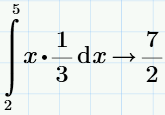

I det at vi ved at dette er en uniformfordeling kan vi slå og i en tabel og se at en muligformel er :


$$E\left\lbrack X\right\rbrack =\frac{a+b}{2}=\frac{5+2}{2}=\frac{7}{2}$$


***Variance:***

variancen af x kan findes ved nedenstående formel:


$$\mathrm{var}\left(x\right)=E|X^2 |-E|X|^2$$


Vi har allerede fundet forventnings værdien $E\left\lbrack X\right\rbrack$ og derfor ved vi at $E\left|X{\left|\right.}^2 ={\left(\frac{7}{2}\right)}^2 \right.$

Vi skal derfor finde $E\left|X^2 \right|$, hvilket udføres ved samme formel som der blev brugt til at finde forventningsværdien dog hvor $x$ udskiftes med $x^2$ derfor kan vi skrive formlen:


$$E\left\lbrack X^2 \right\rbrack =\int_{-\infty \;}^{\infty } {x^2 \cdot f}_x \left(x\right)\mathrm{dx}=\int_2^5 x^2 \cdot \frac{1}{3}\;\mathrm{dx}\Rightarrow 13$$


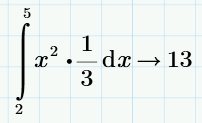

Vi kan nu udregne variancen.

13-(7/2)^2

ans = 0.7500

 
$$\textrm{var}\left(x\right)=E\left|X^2 \right|-E\left|X{\left|\right.}^2 =13-{\left(\frac{7}{2}\right)}^2 =0\ldotp 75=\frac{3}{4}\right.$$


vi har derfor en forventningsværdi på  $E\left\lbrack X\right\rbrack =\frac{7}{2}$ og en varians på $\mathrm{var}\left(x\right)=\frac{3}{4}$